# Example 1: Fitting the parameters to the model using simulated data

The generalized SEIR model inspired by [1] is used to simulate epidemic breakout. Although ref. [1] is a preprint that has not been peer-reviewed, it relies on a fairly standard model that I am using here. 

In [1], there are seven different states

- Susceptibles cases S(t)

- Insusceptibles cases P(t)

- Exposed cases E(t)

- Infectious cases I(t)

- Quarantined cases Q(t)

- Recovered cases R(t)

- Dead cases D(t)

The parameters are as follows:

- alpha: protection rate

- beta: infection rate

- gamma: Inverse of the average latent time

- delta: inverse of the average quarantine time

- lambda0 and lambda1: coefficients used in the time-dependant cure rate

- kappa0 and kappa1: coefficient used in the time-dependant mortality rate

The population is assumed constant, i.e. the births and natural death are not modelled. The cure rate and death rate are here time-dependant but they need some empirical coefficients to tune the time-dependency of these parameters.

The generalized SEIR model is as follows:


$$\frac{\mathrm{d}S(t)}{\mathrm{d}t} = -\alpha S(t) -\beta \frac{S(t)I(t)}{N_{pop}}  \\
\frac{\mathrm{d}E(t)}{\mathrm{d}t} = -\gamma E(t) +\beta \frac{S(t)I(t)}{N_{pop}}  \\
\frac{\mathrm{d}I(t)}{\mathrm{d}t} = \gamma E(t) -\delta I(t)  \\
\frac{\mathrm{d}Q(t)}{\mathrm{d}t} = \delta I(t) -\lambda(t)Q(t) - \kappa(t) Q(t)  \\
\frac{\mathrm{d}R(t)}{\mathrm{d}t} = \lambda(t) Q(t) \\
\frac{\mathrm{d}D(t)}{\mathrm{d}t} = \kappa(t) Q(t) \\
\frac{\mathrm{d}P(t)}{\mathrm{d}t} = \alpha S(t) $$


Here, I simply decided to model $\kappa \left(t\right)$ and $\lambda \left(t\right)$  as:


$$\kappa \left(t\right)=\kappa_0 \;\exp \left(-\kappa_{1\;} t\right)\;$$



$$\lambda \;\left(t\right)=\lambda_0 \;\left\lbrack 1-\exp \left(-\lambda_1 \;t\right)\right\rbrack$$


The system of ODEs can be re-written in a matrix form:


$$\frac{\textrm{dY}}{\textrm{dt}}=A*Y+F$$


where 


$$Y={\left\lbrack S,E,I,Q,R,D,P\right\rbrack }^{\top } \;$$



$$A=\left\lbrack \begin{array}{cccccccc}
-\alpha  & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & -\gamma  & 0 & 0 & 0 & 0 & 0 & 0\\
0 & \gamma  & -\delta  & 0 & 0 & 0 & 0 & 0\\
0 & 0 & \delta  & -\kappa \left(t\right)-\lambda \left(t\right) & 0 & 0 & 0 & 0\\
0 & 0 & 0 & \lambda \left(t\right) & 0 & 0 & 0 & 0\\
0 & 0 & 0 & \kappa \left(t\right) & 0 & 0 & 0 & 0\\
\alpha  & 0 & 0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$



$$F=S\left(t\right)\cdot \;I\left(t\right)\cdot \left\lbrack \begin{array}{c}
-\frac{\beta }{N_{\textrm{pop}} }\\
\frac{\beta }{N_{\textrm{pop}} }\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


The equation $\frac{\textrm{dY}}{\textrm{dt}}=A*Y+F$ is solved using the classic 4th order  Runge-Kutta method.

References

[1] https://arxiv.org/pdf/2002.06563.pdf

## Initialisation

Case of an imaginary epidemy outbreak that took place on 2010-01-01. The simulation time is set to 9 months.

clearvars;close all;clc;

% Time definition
dt = 0.1; % time step
time1 = datetime(2010,01,01,0,0,0):dt:datetime(2010,09,01,0,0,0);
N = numel(time1);
t = [0:N-1].*dt;

## Generate the data

Npop= 60e6; % population (60 millions)
Q0 = 200; % Initial number of infectious that have bee quanrantined
I0 = Q0; % Initial number of infectious cases non-quarantined
E0 = 0; % Initial number of exposed
R0 = 0; % Initial number of recovereds
D0 = 1; % Initial number of deads
alpha = 0.08; %  protection rate
beta = 0.9; %  infection rate
gamma= 1/2; % inverse of average latent time
delta= 1/8; % inverse of average quarantine time
Lambda01 = [0.03 0.05]; % cure rate (time dependant)
Kappa01 =  [0.03 0.05]; % mortality rate (time dependant)
[S,E,I,Q,R,D,P] = SEIQRDP(alpha,beta,gamma,delta,Lambda01,Kappa01,Npop,E0,I0,Q0,R0,D0,t);

## Fit the data

The fitting is done using the time histories of the number of quarantined $Q\left(t\right)$, recovered $R\left(t\right)$ and deads $D\left(t\right)$ only. The number of exposed,  susceptible, insusceptible and infectious is computed in the model but not used as target.

guess = [0.05,0.9,1/4,1/10,0.03,0.03,0.02,0.06]; % initial guess
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = fit_SEIQRDP(Q,R,D,Npop,E0,I0,time1,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9     3.21013e+13                      4.14e+15
     1         18     4.29202e+12      0.0144713        5.7e+14      
     2         27     4.12496e+11      0.0200538       7.94e+13      
     3         36     2.30992e+10      0.0438648        9.2e+12      
     4         45     5.52474e+09      0.0369572       1.98e+11      
     5         54     5.10362e+08       0.223926       6.51e+10      
     6         63     1.01745e+07      0.0543787       2.94e+10      
     7         72      2.8199e+06      0.0072875       1.61e+09      
     8         81      2.8199e+06      0.0251752       1.61e+09      
     9         90     1.76025e+06     0.00629379       1.08e+10      
    10         99      1.3007e+06      0.0138982       4.67e+10      
    11        108          171652     0.00240142       8.53e+08      
    12        117          10307


[S1,E1,I1,Q1,R1,D1,P1] =...
    SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison beween fitted and generated time histories

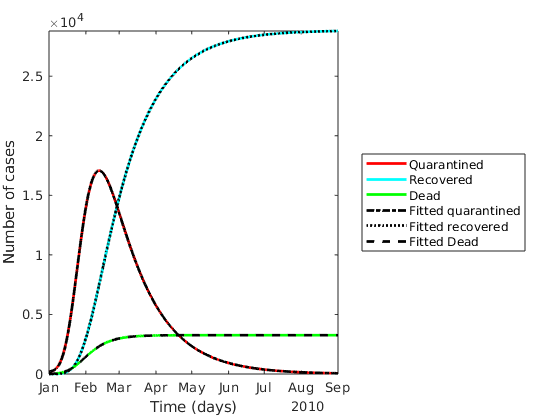

figure
clf;close all;
plot(time1,Q,'r',time1,R,'c',time1,D,'g','linewidth',2);
hold on
plot(time1,Q1,'k-.',time1,R1,'k:',time1,D1,'k--','linewidth',2);
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('Time (days)')
leg = {'Quarantined','Recovered','Dead','Fitted quarantined','Fitted recovered','Fitted Dead'};
legend(leg{:},'location','eastoutside')
set(gcf,'color','w')
axis tight

## Case where the recovered (R) and quarantined (Q) data are not available separately

The  number of qarantined and recovered is unknwon but Q + R is known.

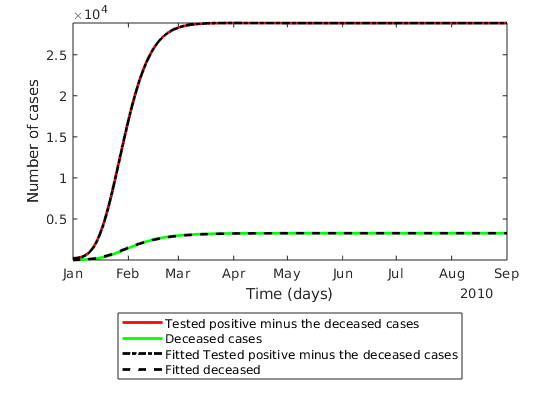

guess = [0.05,0.9,1/4,1/10,0.03,0.03,0.02,0.06]; % initial guess

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = fit_SEIQRDP(Q+R,[],D,Npop,E0,I0,time1,guess,'Display','off');

[S1,E1,I1,Q1,R1,D1,P1] =...
    SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

figure
clf;close all;
plot(time1,Q+R,'r',time1,D,'g','linewidth',2);
hold on
plot(time1,Q1+R1,'k-.',time1,D1,'k--','linewidth',2);
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('Time (days)')
leg = {'Tested positive minus the deceased cases','Deceased cases','Fitted Tested positive minus the deceased cases','Fitted deceased'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
axis tight